# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
% which 
conf = 'CSNESiteVisit';
%conf = 'NeuroModulation';
%conf = 'NeuroModulationV2';

%conf = 'NeuroModulationV3';
%conf = 'NeuroModulationV4';
% 6/17/_2016 try neuromdoulation 
for i = 8:length(SIDS)-3
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2eepSTATSsig'))
            betaChan = 31;
                       betaChan = 14;

            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
                      betaChan = 14;

            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{betaChan});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                

                            if (strcmp(conf,'NeuroModulation') | strcmp(conf,'NeuroModulationV2')| strcmp(conf,'NeuroModulationV4')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                tB = [tB tempBase'];
                t1 = [t1 tempResp1'];
                t2 = [t2 tempResp2'];
                t3 = [t3 tempResp3'];
                            else
                            tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
            end
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            
            % 6-17-2016 - have to transpose for 'conf'
                            if (strcmp(conf,'NeuroModulation')| strcmp(conf,'NeuroModulationV4') | strcmp(conf,'NeuroModulationV2')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                           typeResp = [tempResp3' tempResp2' tempResp1' tempBase'];
            else
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            end
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
       % anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
         %       anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
             % anovaType = [anovaType typeNums];
        
        
    end
end

sid = 0b5a2e

sid = 0b5a2ePlayback

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =    1.0e-03 *

    0.0000
    0.0000
    0.4636


tbl =     'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims'                 [3.8249e+04]    [   3]    [        0]    [1.2750e+04]    [13.1351]    [1.8961e-08]
    'anovaBetaSID'                  [4.7584e+04]    [   1]    [        0]    [4.7584e+04]    [49.0228]    [4.0979e-12]
    'anovaNumStims*anovaBetaSID'    [1.7481e+04]    [   3]    [        0]    [5.8270e+03]    [ 6.0031]    [4.6356e-04]
    'Error'                         [1.2269e+06]    [1264]    [        0]    [  970.6586]           []              []
    'Total'                         [1.3235e+06]    [1271]    [        0]              []           []              []


stats =          source: 'anovan'
          resid: [1272×1 double]
         coeffs: [15×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×15 double]
            dfe: 1264
            mse: 970.6586
    nullproject: [15×8 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {15×1 cell}
           vars: [15×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


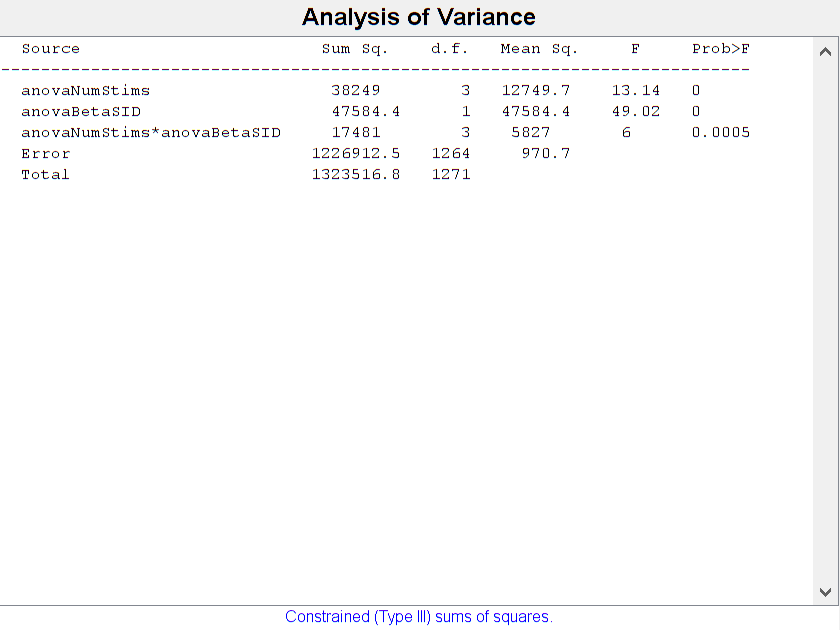

close all;
figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'})
% 
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% [p,tbl,stats] = anovan(anova2,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% 

%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction')

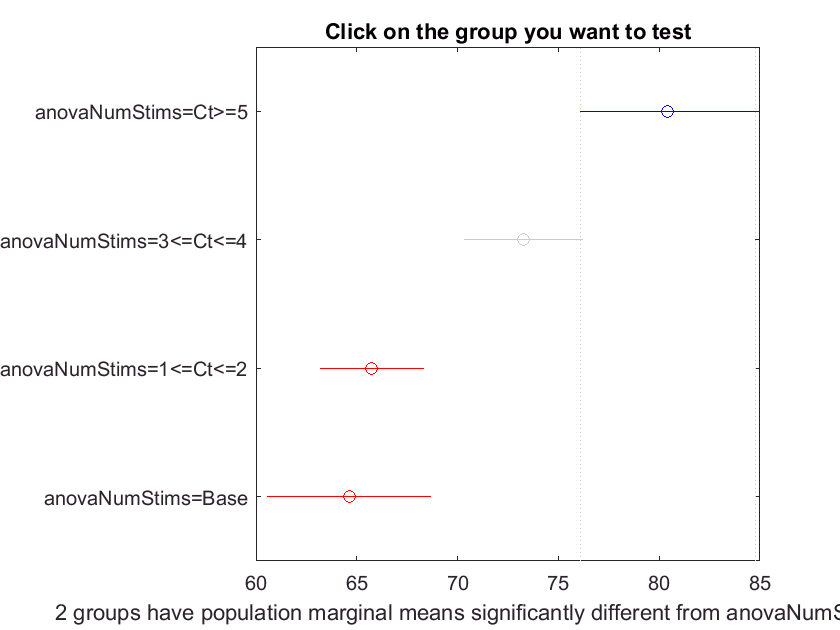

c =     1.0000    2.0000   -0.1808    7.1482   14.4771    0.0590
    1.0000    3.0000    7.7066   14.6698   21.6330    0.0000
    1.0000    4.0000    7.4821   15.7938   24.1055    0.0000
    2.0000    3.0000    2.0993    7.5216   12.9439    0.0021
    2.0000    4.0000    1.5747    8.6457   15.7167    0.0091
    3.0000    4.0000   -5.5672    1.1240    7.8153    0.9731


m =    80.4193    2.3484
   73.2711    1.6197
   65.7495    1.3533
   64.6254    2.2254


h =   Figure (3: Multiple comparison of population marginal means) with properties:

      Number: 3
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


%[p,tbl,stats] = anova2(anovaTotalMags,anovaBetaSID)

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [80.4193]    [2.3484]
    'anovaNumStims=3<=Ct<=4'    [73.2711]    [1.6197]
    'anovaNumStims=1<=Ct<=2'    [65.7495]    [1.3533]
    'anovaNumStims=Base'        [64.6254]    [2.2254]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('CCEP Magnitude (\muV)','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [60 85]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [60 85]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [60 85]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


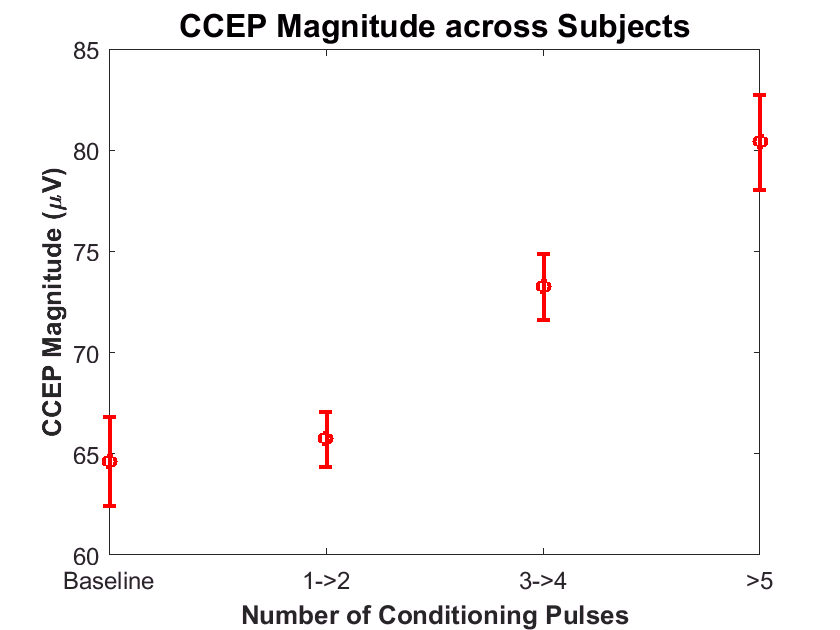

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Conditions';},'fontsize',16,'fontweight','bold')

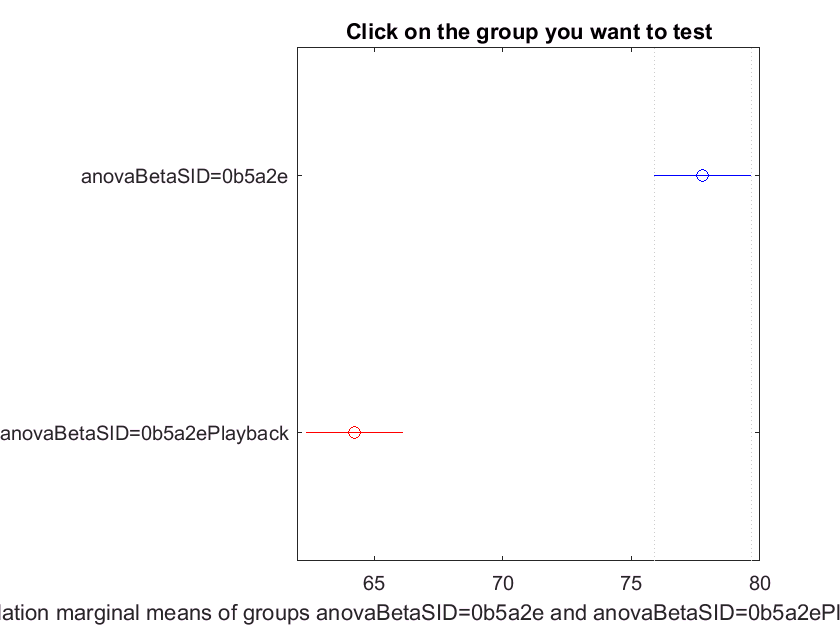

results1 =     1.0000    2.0000    9.7379   13.5234   17.3090    0.0000



figure
results1 = multcompare(stats,'Dimension',[2])

cM =     1.0000    2.0000    2.1416   14.3696   26.5976    0.0088
    1.0000    3.0000   14.0169   25.6347   37.2525    0.0000
    1.0000    4.0000   12.6617   26.5294   40.3971    0.0000
    1.0000    5.0000   13.7488   27.9844   42.2200    0.0000
    1.0000    6.0000   15.6831   27.9111   40.1392    0.0000
    1.0000    7.0000   20.0714   31.6893   43.3071    0.0000
    1.0000    8.0000   19.1750   33.0426   46.9103    0.0000
    2.0000    3.0000    2.2182   11.2651   20.3120    0.0040
    2.0000    4.0000    0.3622   12.1599   23.9575    0.0379
    2.0000    5.0000    1.3868   13.6148   25.8428    0.0169


mM =    94.4114    3.3212
   80.0419    2.2906
   68.7767    1.9139
   67.8820    3.1472
   66.4271    3.3212
   66.5003    2.2906
   62.7222    1.9139
   61.3688    3.1472


hM =   Figure (6: Multiple comparison of population marginal means) with properties:

      Number: 6
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaBetaSID=0b5a2e'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=0b5a2e'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=0b5a2e'
    'anovaNumStims=Base,anovaBetaSID=0b5a2e'
    'anovaNumStims=Ct>=5,anovaBetaSID=0b5a2ePlayback'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=0b5a2ePlayback'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=0b5a2ePlayback'
    'anovaNumStims=Base,anovaBetaSID=0b5a2ePlayback'


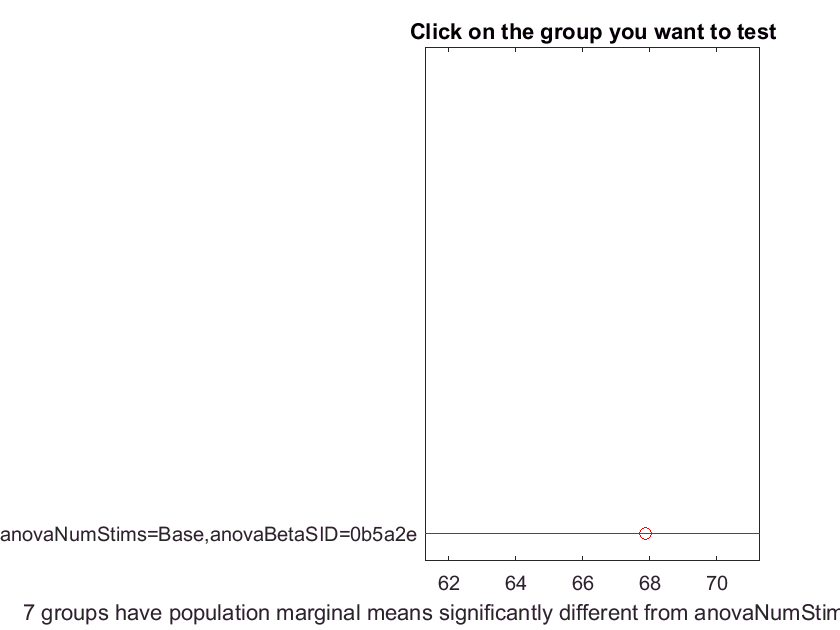

ax =   Axes with properties:

             XLim: [1 8]
             YLim: [55 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [1 8]
             YLim: [55 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


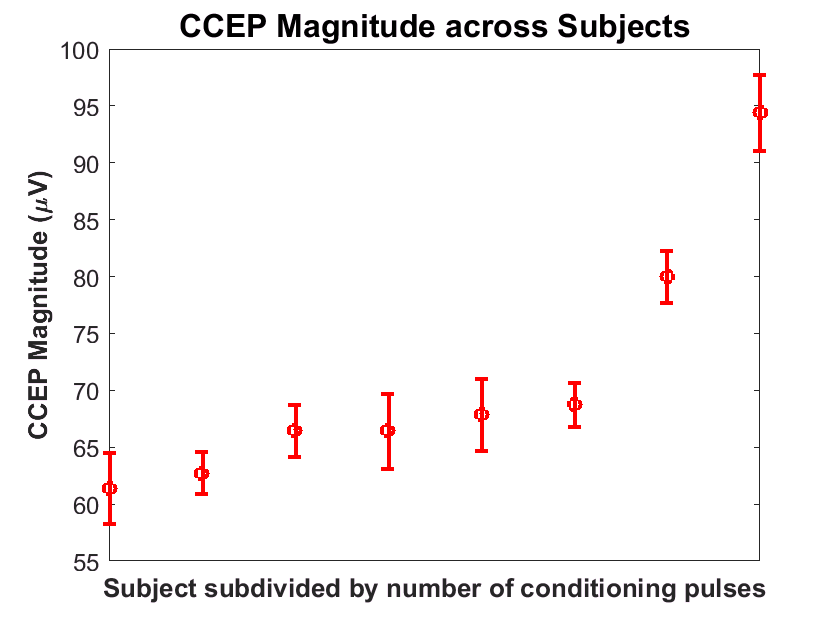



% figure
% results = multcompare(stats,'Dimension',[3])

figure

ans =     1.0000    2.0000   -0.1808    7.1482   14.4771    0.0590
    1.0000    3.0000    7.7066   14.6698   21.6330    0.0000
    1.0000    4.0000    7.4821   15.7938   24.1055    0.0000
    2.0000    3.0000    2.0993    7.5216   12.9439    0.0021
    2.0000    4.0000    1.5747    8.6457   15.7167    0.0091
    3.0000    4.0000   -5.5672    1.1240    7.8153    0.9731


[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])
errorbar((1:length(mM(:,1))),flip(mM(:,1)),flip(mM(:,2)),'ro','linestyle','none','linew',2','color','r')
ylabel('CCEP Magnitude (\muV)','fontsize',14,'fontweight','bold')
xlabel('Subject subdivided by number of conditioning pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'
ax.XTick = []
%ax.XTickLabel = {'Baseline','1->2','3->4','>5' }
ax.FontSize = 12;
% ax.FontWeight = 'bold';
xlim([0 9])
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

figure
multcompare(stats,'Dimension',[1])